## Bonus: Classify Dirt vs. Normal pills 

% Load Data
CropsDS = imageDatastore("PillsCrops",IncludeSubfolders=true,LabelSource="foldernames");

NormalCropsDS = subset(CropsDS,CropsDS.Labels=="Normal");
NormalMaskDS = transform(NormalCropsDS,@segmentPill);
propNormalValues = readall(transform(NormalMaskDS,@calculateRegionProps));

DirtCropsDS = subset(CropsDS,CropsDS.Labels=="Dirt");
DirtMaskDS = transform(DirtCropsDS,@segmentPill);
propDirtValues = readall(transform(DirtMaskDS,@calculateRegionProps));

propNames = ["Area", "Eccentricity", "Circularity", "EquivDiameter", "Perimeter"];

**Select Region Property**

viewProperty = 3;

**View HIstogram**

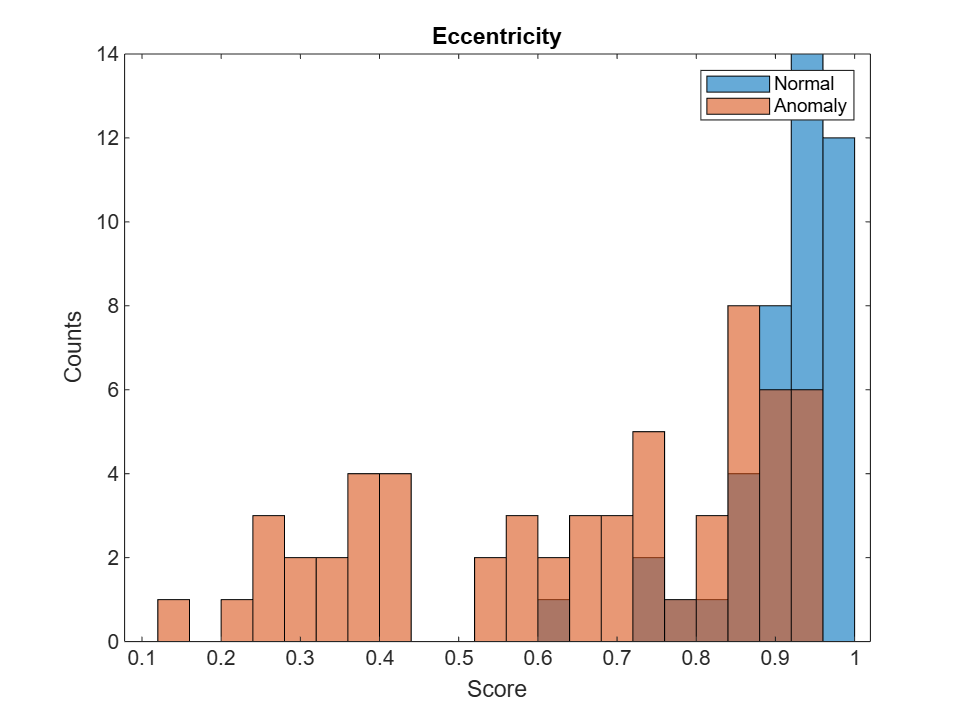

figure 
hNormal = histogram(propNormalValues(:,viewProperty), 10);
hold on
hAnomaly = histogram(propDirtValues(:,viewProperty), 10, BinWidth=hNormal.BinWidth);
hold off

legend([hNormal,hAnomaly],"Normal","Anomaly")
title(propNames(viewProperty))
xlabel("Score");
ylabel("Counts");

**Calculate Anomaly Threshold**

[normalScores, dirtScores, dirtFlipVec] = calculateScores(propNormalValues,propDirtValues);

scores = [normalScores(:,viewProperty); dirtScores(:,viewProperty)];
labels = [NormalCropsDS.Labels; DirtCropsDS.Labels];

threshold = anomalyThreshold(labels,scores,"Dirt","MaxF1Score");
disp("Threshold = " + abs(threshold))

Threshold = 0.94372


**Visualize Confusion Matrix**

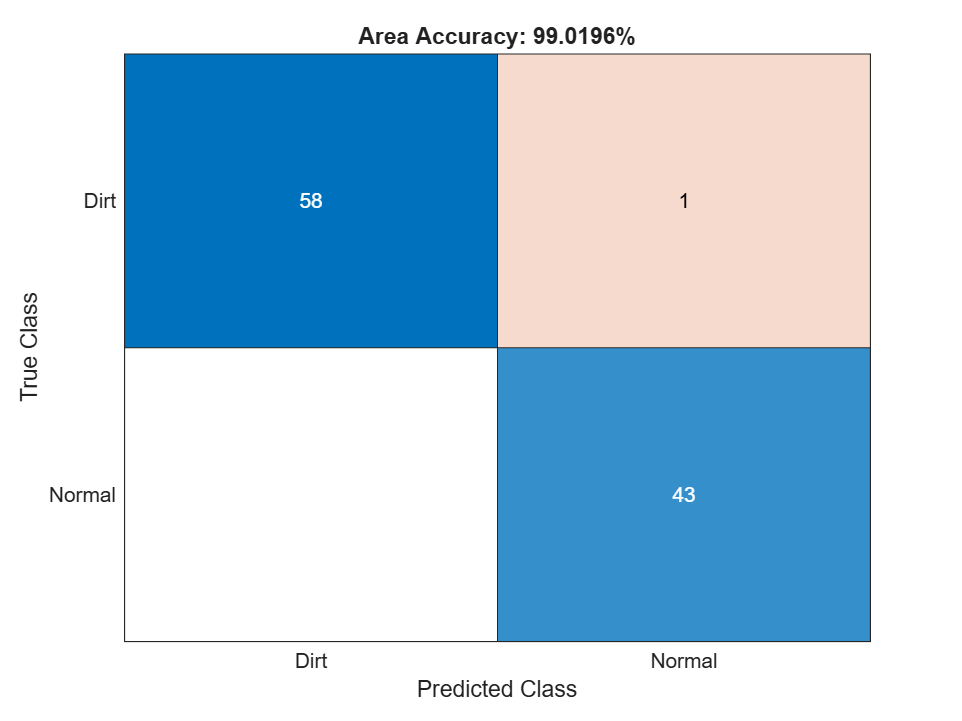

NormalDirtCropsDS = subset(CropsDS, CropsDS.Labels=="Normal" | CropsDS.Labels=="Dirt");
NormalDirtMaskDS = transform(NormalDirtCropsDS,@segmentPill);
propValues = readall(transform(NormalDirtMaskDS,@calculateRegionProps)).*dirtFlipVec;


values = propValues(:,viewProperty);
propLog = values >= threshold;

predictedLabels = "";
predictedLabels(propLog) = "Dirt"; 
predictedLabels(~propLog) = "Normal";

expectedLabels = string(NormalDirtCropsDS.Labels)';
accuracy = sum(expectedLabels==predictedLabels)/numel(expectedLabels);
figure;
confusionchart(expectedLabels,predictedLabels);
title(propNames(viewProperty) + " Accuracy: " + accuracy*100 + "%")

*Copyright 2025, The MathWorks, Inc.*